clc;
clear ;
close all;
%transfer function
m = 1;
b = 10;
k = 20;
F = 1;
s = tf('s');
P = 1/(s^2 + 10*s + 20)

P =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties


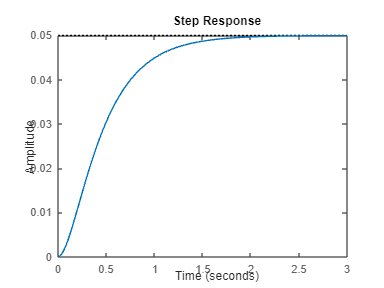

%step response without controller 
figure(1);
step(P);


%step response with p-controller 
Kp = 300;
C = pid(Kp)

C =
 
  Kp = 300
 
P-only controller.
Model Properties


T = feedback(C*P,1)

T =
 
        300
  ----------------
  s^2 + 10 s + 320
 
Continuous-time transfer function.
Model Properties


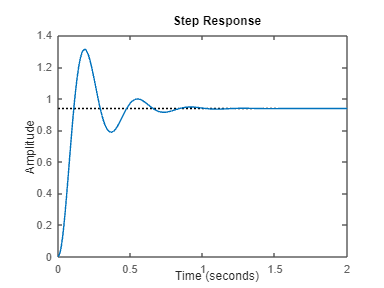


t = 0:0.01:2;
figure(2);

step(T,t);


Kp = 300;
Kd = 10;
C = pid(Kp,0,Kd)

C =
 
             
  Kp + Kd * s
             

  with Kp = 300, Kd = 10
 
Continuous-time PD controller in parallel form.
Model Properties


T = feedback(C*P,1)

T =
 
     10 s + 300
  ----------------
  s^2 + 20 s + 320
 
Continuous-time transfer function.
Model Properties


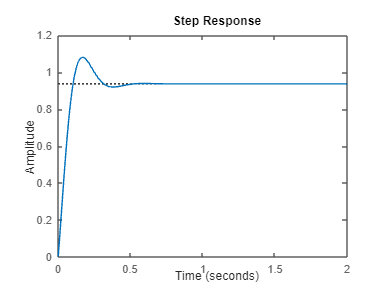


t = 0:0.01:2;
figure(3);
step(T,t)


%step response with pi-controller
Kp = 30;
Ki = 70;
C = pid(Kp,Ki)

C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 30, Ki = 70
 
Continuous-time PI controller in parallel form.
Model Properties


T = feedback(C*P,1)

T =
 
         30 s + 70
  ------------------------
  s^3 + 10 s^2 + 50 s + 70
 
Continuous-time transfer function.
Model Properties


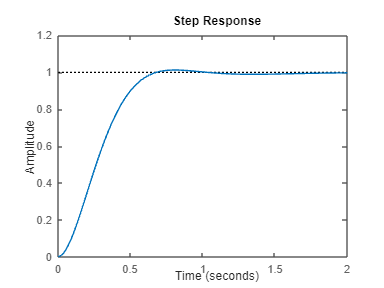

figure(4);

t = 0:0.01:2;
step(T,t)

%step response with pid-controller
Kp = 350;
Ki = 300;
Kd = 50;
C = pid(Kp,Ki,Kd)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 350, Ki = 300, Kd = 50
 
Continuous-time PID controller in parallel form.
Model Properties


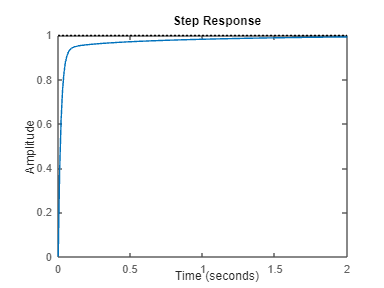

T = feedback(C*P,1);
figure(5);

t = 0:0.01:2;
step(T,t)

%step response with pid-controller
Kp = 650;
Ki = 300;
Kd = 50;
C = pid(Kp,Ki,Kd)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 650, Ki = 300, Kd = 50
 
Continuous-time PID controller in parallel form.
Model Properties


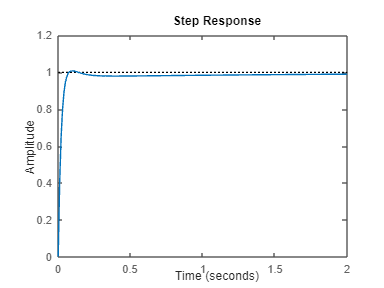

T = feedback(C*P,1);
figure(6);

t = 0:0.01:2;
step(T,t)

%pid tuner
pidTuner(P,'p');
pidTuner(P,C);
opts = pidtuneOptions('CrossoverFrequency',32,'PhaseMargin',90);
[C, info] = pidtune(P, 'pid', opts)

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 320, Ki = 796, Kd = 32.2
 
Continuous-time PID controller in parallel form.
Model Properties


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 32
           PhaseMargin: 90
